# Exercise 5.2 - C Major Scale

## METHOD #1

% % C major scale (frequencies)
% scaleFreq = [261.6 293.7 329.6 349.2 392 440 493.9 523.3] .';
% % log2(522 / 262) = 0,99 = 1 octava
% 
% Generate tones with a sampling frequency of 8 kHz, an amplitude of 1V
% and a duration of 300 ms.
% fs = 8000;
% n = 0 : (0.3 * fs) - 1;
% newFreq = 1/fs * scaleFreq;
% tones = zeros(8, length(n));
% 
% for i = 1 : length(newFreq) 
%     tones(i, :) = cos(2*pi * newFreq(i) * n);
% end
% 
% tones = tones .';
% scale = tones(:);
% sound(scale, fs);
%
% Export out the signal into a WAV file.
% audiowrite('audio\scale.wav', scale, fs);

## METHOD #2

% C major scale (frequencies).
c4ScaleFreq = [261.6 293.7 329.6 349.2 392 440 493.9 523.3] .';

% Check that the calculated frequencies do correlate with a full octave.
numOctaves = round(log2(522 / 262), 1)

numOctaves = 1

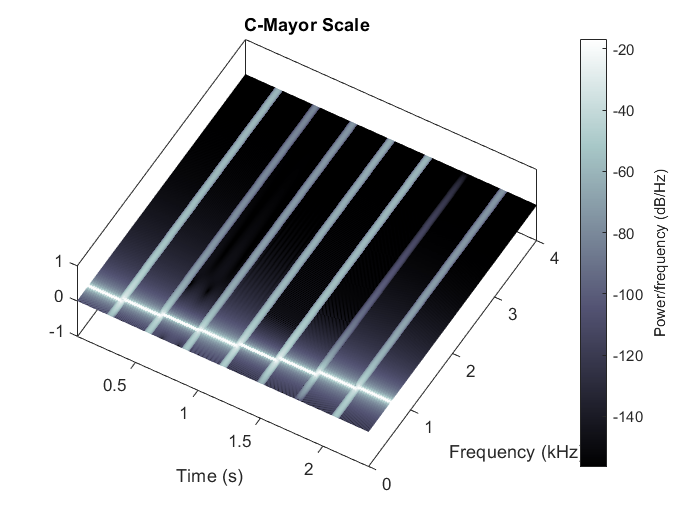

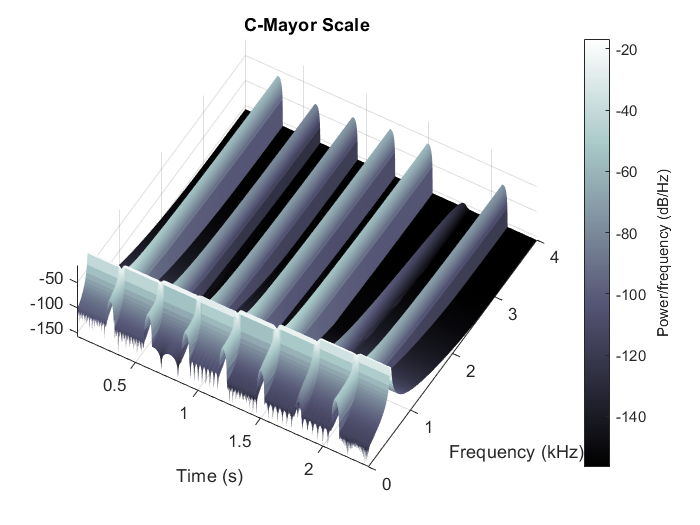


fs = 8000;              % Sampling frequency.
n = 0 : (0.3 * fs) - 1; % Discrete time.

% Generate tones with a sampling frequency of 8 kHz, an amplitude of 1V
% and a duration of 300 ms.
c4ScaleMatrix = cos(2*pi * c4ScaleFreq/fs * n) .';

% Concatenate all tones and play the resulting signal.
c4ScaleVector = c4ScaleMatrix(:);
sound(c4ScaleVector, fs);

% Export out the signal and plot its spectrogram.
audiowrite('audio\c4Scale.wav', c4ScaleVector, fs);
spectrogram(c4ScaleVector, hanning(512), 500, 512, fs, 'yaxis');
title('C-Mayor Scale'), colormap bone, view(30, 75);